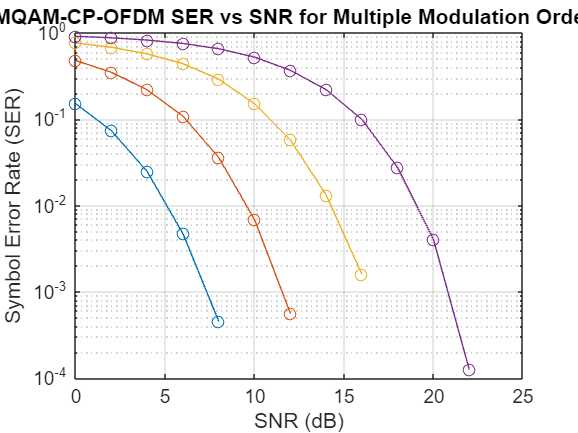

N = 64; % Number of subcarriers
CP_len = 16; % Length of the cyclic prefix
EbN0_db = 0:2:30; % Range of SNR values in dB
numSymbols = 1000; % Number of OFDM symbols

M_values = [4,16,64,256]; % Different modulation orders
SER = zeros(length(EbN0_db), length(M_values)); % Preallocate SER matrix

for mIdx = 1:length(M_values)
    M = M_values(mIdx); % Current modulation order
    
    for idx = 1:length(EbN0_db)
        % Generate random data symbols
        data = randi([0 M-1], N, numSymbols);
        
        % Modulate using M-QAM
        modData = qammod(data, M);
        
        % Convert to time domain using IFFT
        ifftData = ifft(modData, N);
        
        % Add cyclic prefix
        cpData = [ifftData(end-CP_len+1:end, :); ifftData];
        
        % Reshape into a 1D array for transmission
        txSignal = cpData(:);
        
        % Convert Eb/N0 to SNR and add AWGN
        snr = EbN0_db(idx) + 10*log10(log2(M));
        rxSignal = awgn(txSignal, snr, 'measured');
        
        % Reshape back to matrix form
        rxSignal = reshape(rxSignal, N+CP_len, numSymbols);
        
        % Remove cyclic prefix
        rxSignalNoCp = rxSignal(CP_len+1:end, :);
        
        % Convert back to frequency domain using FFT
        fftData = fft(rxSignalNoCp, N);
        
        % Demodulate the received signal
        demodData = qamdemod(fftData, M);
        
        % Calculate the number of symbol errors
        numSymbolErrors = sum(sum(data ~= demodData));
        
        % Compute Symbol Error Rate (SER)
        SER(idx, mIdx) = numSymbolErrors / (N * numSymbols);
    end
end

% Plotting SER vs SNR
figure;
semilogy(EbN0_db, SER, 'o-');
title('MQAM-CP-OFDM SER vs SNR for Multiple Modulation Orders');
xlabel('SNR (dB)');
ylabel('Symbol Error Rate (SER)');
grid on;